MODE = 0 % 0 is using randomly generated topology and parameters, 1 is using history communication topology and IACs parameters

MODE = 0

DELAY = 0 % 0 is no time-delay, 1 is the case that time-delay will not destroy the feasibility

DELAY = 0

            % 2 is the case that time-delay will destroy the feasibility
ISSUE_PERIOD=2;  % Set issue period

if(MODE==0)
    N=100;
    L=zeros(N,N);
    eig2=0;
    while(eig2<0.001)
    L=zeros(N,N);    
    for i=1:N
        p=0;
        while(p<0.6 || p>0.9 )
            p=rand;
        end
        for j=i+1:N
            if(rand>p)
                L(i,j)=-1;
                L(j,i)=-1;
            end
        end
        L(i,i)=-sum(L(i,1:N));
    end
    eigen=eig(L);
    eig2=eigen(2);
    end
    L
    eig(L)
    D=zeros(N,N);
    while(D==zeros(N,N))
    for i=1:N
        if(rand>0.9)
            D(i,i)=1;
        end
    end
    end
    sum(sum(D,2))
end

L =     39     0     0     0     0    -1     0    -1     0     0     0    -1    -1     0     0     0    -1    -1    -1    -1     0     0     0     0     0     0     0     0    -1    -1    -1     0     0     0     0     0     0    -1     0     0    -1    -1    -1     0     0    -1    -1     0     0     0
     0    14     0     0     0     0     0     0    -1     0     0    -1     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1    -1     0     0     0     0     0    -1     0     0     0     0     0     0     0    -1     0     0
     0     0    39     0     0     0    -1     0     0     0    -1     0    -1    -1     0     0     0    -1     0     0     0     0     0     0    -1     0     0     0     0     0    -1    -1     0     0    -1    -1    -1     0    -1     0     0     0     0     0    -1     0    -1     0     0     0
     0     0     0    20     0    -1     0     0     0     0     0     0     0    -1     0   

ans =     0.0000
    8.6493
   12.4868
   12.9632
   13.3361
   13.9644
   14.3284
   14.5971
   14.6152
   15.2750


ans = 12

% Setting the parameters of the IACs
% different parameters will result in different control effect
if(MODE==0)
    CT=1.9+0.2*rand(N,1); 
    RT=(1.9+0.2*rand(N,1))*10; 
    theta=(2.3+0.4*rand(N,1))/10;
    Tref=22+2*rand(N,1);
    dT=1.8+0.4*rand(N,1);
end
Ta=32;
A=diag(-1./(CT.*RT));
B=diag(-theta./(2*dT.*CT));
C=diag((Ta-Tref+dT)./(2*dT.*CT.*RT));


beta=0.25;

% Initializing the power of IACs
if(MODE==0)
    P0=5.6;
    P=0.25*P0+0.1*P0*rand(N,1);
    P_init=P;
else
    P=P_init;
end

% Initializing the state of IACs
if(MODE==0)
    x=0.3+0.5*rand(N,1);
    x_init=x;
else
    x=x_init;
end
v=zeros(N,1);
u=zeros(N,1);

for i=1:N
    v(i)=A(i,i)*x(i)+B(i,i)*P(i)+C(i,i);
end

if(DELAY==0)
    delay=0.001 % Due to the indexing problem of matlab, a very small number is added here to avoid problems
elseif(DELAY==1)
    delay=2.0 % feasible case
elseif(DELAY==2)
    delay=2.85 % infeasible case
end

delay = 1.0000e-03

dd=round(delay/0.001)

dd = 1

T_total=1000;

P_t=zeros(1,500001);
Pobj_t=zeros(1,500001);
x_t=zeros(N,500001);
v_t=zeros(N,500001);
P_sum=sum(P);

for t=0:0.001:T_total
    n=round(t/0.001)+1;

    P_obj=(1.9+0.02*sin(0.2*t)+0.05*sin(0.05*t)+0.05*sin(0.01*t)+0.02*sin(0.5*t))*N;

    Pi=inv(B)*(v-A*x-C*ones(N,1));
    P_sum=sum(Pi);

    dP=P_obj-P_sum;
    if(t>delay)
        v_delay=v_t(1:N,n-dd);
        x_delay=x_t(1:N,n-dd);
        u=beta*L*x_delay;
    else
        u=zeros(N,1);
    end
    
    x=x+0.001*v;
    
    if(mod(t,ISSUE_PERIOD)==0)
        dPP=dP/sum(sum(D))*ones(N,1);
        v=v+(B*D*dPP);
    end
    
    v=v+0.001*(A*v+B*u);

    P_t(n)=P_sum;
    Pobj_t(n)=P_obj;
    x_t(1:N,n)=x;
    v_t(1:N,n)=v;
    if(mod(n,1000)==0)
        n
    end
end 

n = 1000

n = 2000

n = 3000

n = 4000

n = 5000

n = 6000

n = 7000

n = 8000

n = 9000

n = 10000

n = 11000

n = 12000

n = 13000

n = 14000

n = 15000

n = 16000

n = 17000

n = 18000

n = 19000

n = 20000

n = 21000

n = 22000

n = 23000

n = 24000

n = 25000

n = 26000

n = 27000

n = 28000

n = 29000

n = 30000

n = 31000

n = 32000

n = 33000

n = 34000

n = 35000

n = 36000

n = 37000

n = 38000

n = 39000

n = 40000

n = 41000

n = 42000

n = 43000

n = 44000

n = 45000

n = 46000

n = 47000

n = 48000

n = 49000

n = 50000

n = 51000

n = 52000

n = 53000

n = 54000

n = 55000

n = 56000

n = 57000

n = 58000

n = 59000

n = 60000

n = 61000

n = 62000

n = 63000

n = 64000

n = 65000

n = 66000

n = 67000

n = 68000

n = 69000

n = 70000

n = 71000

n = 72000

n = 73000

n = 74000

n = 75000

n = 76000

n = 77000

n = 78000

n = 79000

n = 80000

n = 81000

n = 82000

n = 83000

n = 84000

n = 85000

n = 86000

n = 87000

n = 88000

n = 89000

n = 90000

n = 91000

n = 92000

n = 93000

n = 94000

n = 95000

n = 96000

n = 97000

n = 98000

n = 99000

n = 100000

n = 101000

n = 102000

n = 103000

n = 104000

n = 105000

n = 106000

n = 107000

n = 108000

n = 109000

n = 110000

n = 111000

n = 112000

n = 113000

n = 114000

n = 115000

n = 116000

n = 117000

n = 118000

n = 119000

n = 120000

n = 121000

n = 122000

n = 123000

n = 124000

n = 125000

n = 126000

n = 127000

n = 128000

n = 129000

n = 130000

n = 131000

n = 132000

n = 133000

n = 134000

n = 135000

n = 136000

n = 137000

n = 138000

n = 139000

n = 140000

n = 141000

n = 142000

n = 143000

n = 144000

n = 145000

n = 146000

n = 147000

n = 148000

n = 149000

n = 150000

n = 151000

n = 152000

n = 153000

n = 154000

n = 155000

n = 156000

n = 157000

n = 158000

n = 159000

n = 160000

n = 161000

n = 162000

n = 163000

n = 164000

n = 165000

n = 166000

n = 167000

n = 168000

n = 169000

n = 170000

n = 171000

n = 172000

n = 173000

n = 174000

n = 175000

n = 176000

n = 177000

n = 178000

n = 179000

n = 180000

n = 181000

n = 182000

n = 183000

n = 184000

n = 185000

n = 186000

n = 187000

n = 188000

n = 189000

n = 190000

n = 191000

n = 192000

n = 193000

n = 194000

n = 195000

n = 196000

n = 197000

n = 198000

n = 199000

n = 200000

n = 201000

n = 202000

n = 203000

n = 204000

n = 205000

n = 206000

n = 207000

n = 208000

n = 209000

n = 210000

n = 211000

n = 212000

n = 213000

n = 214000

n = 215000

n = 216000

n = 217000

n = 218000

n = 219000

n = 220000

n = 221000

n = 222000

n = 223000

n = 224000

n = 225000

n = 226000

n = 227000

n = 228000

n = 229000

n = 230000

n = 231000

n = 232000

n = 233000

n = 234000

n = 235000

n = 236000

n = 237000

n = 238000

n = 239000

n = 240000

n = 241000

n = 242000

n = 243000

n = 244000

n = 245000

n = 246000

n = 247000

n = 248000

n = 249000

n = 250000

n = 251000

n = 252000

n = 253000

n = 254000

n = 255000

n = 256000

n = 257000

n = 258000

n = 259000

n = 260000

n = 261000

n = 262000

n = 263000

n = 264000

n = 265000

n = 266000

n = 267000

n = 268000

n = 269000

n = 270000

n = 271000

n = 272000

n = 273000

n = 274000

n = 275000

n = 276000

n = 277000

n = 278000

n = 279000

n = 280000

n = 281000

n = 282000

n = 283000

n = 284000

n = 285000

n = 286000

n = 287000

n = 288000

n = 289000

n = 290000

n = 291000

n = 292000

n = 293000

n = 294000

n = 295000

n = 296000

n = 297000

n = 298000

n = 299000

n = 300000

n = 301000

n = 302000

n = 303000

n = 304000

n = 305000

n = 306000

n = 307000

n = 308000

n = 309000

n = 310000

n = 311000

n = 312000

n = 313000

n = 314000

n = 315000

n = 316000

n = 317000

n = 318000

n = 319000

n = 320000

n = 321000

n = 322000

n = 323000

n = 324000

n = 325000

n = 326000

n = 327000

n = 328000

n = 329000

n = 330000

n = 331000

n = 332000

n = 333000

n = 334000

n = 335000

n = 336000

n = 337000

n = 338000

n = 339000

n = 340000

n = 341000

n = 342000

n = 343000

n = 344000

n = 345000

n = 346000

n = 347000

n = 348000

n = 349000

n = 350000

n = 351000

n = 352000

n = 353000

n = 354000

n = 355000

n = 356000

n = 357000

n = 358000

n = 359000

n = 360000

n = 361000

n = 362000

n = 363000

n = 364000

n = 365000

n = 366000

n = 367000

n = 368000

n = 369000

n = 370000

n = 371000

n = 372000

n = 373000

n = 374000

n = 375000

n = 376000

n = 377000

n = 378000

n = 379000

n = 380000

n = 381000

n = 382000

n = 383000

n = 384000

n = 385000

n = 386000

n = 387000

n = 388000

n = 389000

n = 390000

n = 391000

n = 392000

n = 393000

n = 394000

n = 395000

n = 396000

n = 397000

n = 398000

n = 399000

n = 400000

n = 401000

n = 402000

n = 403000

n = 404000

n = 405000

n = 406000

n = 407000

n = 408000

n = 409000

n = 410000

n = 411000

n = 412000

n = 413000

n = 414000

n = 415000

n = 416000

n = 417000

n = 418000

n = 419000

n = 420000

n = 421000

n = 422000

n = 423000

n = 424000

n = 425000

n = 426000

n = 427000

n = 428000

n = 429000

n = 430000

n = 431000

n = 432000

n = 433000

n = 434000

n = 435000

n = 436000

n = 437000

n = 438000

n = 439000

n = 440000

n = 441000

n = 442000

n = 443000

n = 444000

n = 445000

n = 446000

n = 447000

n = 448000

n = 449000

n = 450000

n = 451000

n = 452000

n = 453000

n = 454000

n = 455000

n = 456000

n = 457000

n = 458000

n = 459000

n = 460000

n = 461000

n = 462000

n = 463000

n = 464000

n = 465000

n = 466000

n = 467000

n = 468000

n = 469000

n = 470000

n = 471000

n = 472000

n = 473000

n = 474000

n = 475000

n = 476000

n = 477000

n = 478000

n = 479000

n = 480000

n = 481000

n = 482000

n = 483000

n = 484000

n = 485000

n = 486000

n = 487000

n = 488000

n = 489000

n = 490000

n = 491000

n = 492000

n = 493000

n = 494000

n = 495000

n = 496000

n = 497000

n = 498000

n = 499000

n = 500000

n = 501000

n = 502000

n = 503000

n = 504000

n = 505000

n = 506000

n = 507000

n = 508000

n = 509000

n = 510000

n = 511000

n = 512000

n = 513000

n = 514000

n = 515000

n = 516000

n = 517000

n = 518000

n = 519000

n = 520000

n = 521000

n = 522000

n = 523000

n = 524000

n = 525000

n = 526000

n = 527000

n = 528000

n = 529000

n = 530000

n = 531000

n = 532000

n = 533000

n = 534000

n = 535000

n = 536000

n = 537000

n = 538000

n = 539000

n = 540000

n = 541000

n = 542000

n = 543000

n = 544000

n = 545000

n = 546000

n = 547000

n = 548000

n = 549000

n = 550000

n = 551000

n = 552000

n = 553000

n = 554000

n = 555000

n = 556000

n = 557000

n = 558000

n = 559000

n = 560000

n = 561000

n = 562000

n = 563000

n = 564000

n = 565000

n = 566000

n = 567000

n = 568000

n = 569000

n = 570000

n = 571000

n = 572000

n = 573000

n = 574000

n = 575000

n = 576000

n = 577000

n = 578000

n = 579000

n = 580000

n = 581000

n = 582000

n = 583000

n = 584000

n = 585000

n = 586000

n = 587000

n = 588000

n = 589000

n = 590000

n = 591000

n = 592000

n = 593000

n = 594000

n = 595000

n = 596000

n = 597000

n = 598000

n = 599000

n = 600000

n = 601000

n = 602000

n = 603000

n = 604000

n = 605000

n = 606000

n = 607000

n = 608000

n = 609000

n = 610000

n = 611000

n = 612000

n = 613000

n = 614000

n = 615000

n = 616000

n = 617000

n = 618000

n = 619000

n = 620000

n = 621000

n = 622000

n = 623000

n = 624000

n = 625000

n = 626000

n = 627000

n = 628000

n = 629000

n = 630000

n = 631000

n = 632000

n = 633000

n = 634000

n = 635000

n = 636000

n = 637000

n = 638000

n = 639000

n = 640000

n = 641000

n = 642000

n = 643000

n = 644000

n = 645000

n = 646000

n = 647000

n = 648000

n = 649000

n = 650000

n = 651000

n = 652000

n = 653000

n = 654000

n = 655000

n = 656000

n = 657000

n = 658000

n = 659000

n = 660000

n = 661000

n = 662000

n = 663000

n = 664000

n = 665000

n = 666000

n = 667000

n = 668000

n = 669000

n = 670000

n = 671000

n = 672000

n = 673000

n = 674000

n = 675000

n = 676000

n = 677000

n = 678000

n = 679000

n = 680000

n = 681000

n = 682000

n = 683000

n = 684000

n = 685000

n = 686000

n = 687000

n = 688000

n = 689000

n = 690000

n = 691000

n = 692000

n = 693000

n = 694000

n = 695000

n = 696000

n = 697000

n = 698000

n = 699000

n = 700000

n = 701000

n = 702000

n = 703000

n = 704000

n = 705000

n = 706000

n = 707000

n = 708000

n = 709000

n = 710000

n = 711000

n = 712000

n = 713000

n = 714000

n = 715000

n = 716000

n = 717000

n = 718000

n = 719000

n = 720000

n = 721000

n = 722000

n = 723000

n = 724000

n = 725000

n = 726000

n = 727000

n = 728000

n = 729000

n = 730000

n = 731000

n = 732000

n = 733000

n = 734000

n = 735000

n = 736000

n = 737000

n = 738000

n = 739000

n = 740000

n = 741000

n = 742000

n = 743000

n = 744000

n = 745000

n = 746000

n = 747000

n = 748000

n = 749000

n = 750000

n = 751000

n = 752000

n = 753000

n = 754000

n = 755000

n = 756000

n = 757000

n = 758000

n = 759000

n = 760000

n = 761000

n = 762000

n = 763000

n = 764000

n = 765000

n = 766000

n = 767000

n = 768000

n = 769000

n = 770000

n = 771000

n = 772000

n = 773000

n = 774000

n = 775000

n = 776000

n = 777000

n = 778000

n = 779000

n = 780000

n = 781000

n = 782000

n = 783000

n = 784000

n = 785000

n = 786000

n = 787000

n = 788000

n = 789000

n = 790000

n = 791000

n = 792000

n = 793000

n = 794000

n = 795000

n = 796000

n = 797000

n = 798000

n = 799000

n = 800000

n = 801000

n = 802000

n = 803000

n = 804000

n = 805000

n = 806000

n = 807000

n = 808000

n = 809000

n = 810000

n = 811000

n = 812000

n = 813000

n = 814000

n = 815000

n = 816000

n = 817000

n = 818000

n = 819000

n = 820000

n = 821000

n = 822000

n = 823000

n = 824000

n = 825000

n = 826000

n = 827000

n = 828000

n = 829000

n = 830000

n = 831000

n = 832000

n = 833000

n = 834000

n = 835000

n = 836000

n = 837000

n = 838000

n = 839000

n = 840000

n = 841000

n = 842000

n = 843000

n = 844000

n = 845000

n = 846000

n = 847000

n = 848000

n = 849000

n = 850000

n = 851000

n = 852000

n = 853000

n = 854000

n = 855000

n = 856000

n = 857000

n = 858000

n = 859000

n = 860000

n = 861000

n = 862000

n = 863000

n = 864000

n = 865000

n = 866000

n = 867000

n = 868000

n = 869000

n = 870000

n = 871000

n = 872000

n = 873000

n = 874000

n = 875000

n = 876000

n = 877000

n = 878000

n = 879000

n = 880000

n = 881000

n = 882000

n = 883000

n = 884000

n = 885000

n = 886000

n = 887000

n = 888000

n = 889000

n = 890000

n = 891000

n = 892000

n = 893000

n = 894000

n = 895000

n = 896000

n = 897000

n = 898000

n = 899000

n = 900000

n = 901000

n = 902000

n = 903000

n = 904000

n = 905000

n = 906000

n = 907000

n = 908000

n = 909000

n = 910000

n = 911000

n = 912000

n = 913000

n = 914000

n = 915000

n = 916000

n = 917000

n = 918000

n = 919000

n = 920000

n = 921000

n = 922000

n = 923000

n = 924000

n = 925000

n = 926000

n = 927000

n = 928000

n = 929000

n = 930000

n = 931000

n = 932000

n = 933000

n = 934000

n = 935000

n = 936000

n = 937000

n = 938000

n = 939000

n = 940000

n = 941000

n = 942000

n = 943000

n = 944000

n = 945000

n = 946000

n = 947000

n = 948000

n = 949000

n = 950000

n = 951000

n = 952000

n = 953000

n = 954000

n = 955000

n = 956000

n = 957000

n = 958000

n = 959000

n = 960000

n = 961000

n = 962000

n = 963000

n = 964000

n = 965000

n = 966000

n = 967000

n = 968000

n = 969000

n = 970000

n = 971000

n = 972000

n = 973000

n = 974000

n = 975000

n = 976000

n = 977000

n = 978000

n = 979000

n = 980000

n = 981000

n = 982000

n = 983000

n = 984000

n = 985000

n = 986000

n = 987000

n = 988000

n = 989000

n = 990000

n = 991000

n = 992000

n = 993000

n = 994000

n = 995000

n = 996000

n = 997000

n = 998000

n = 999000

n = 1000000

t=0:0.001:T_total;

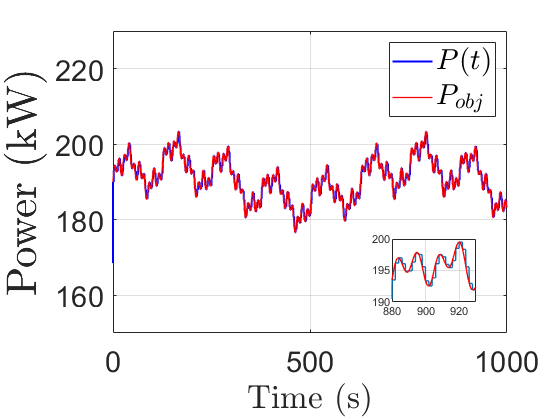

% Power curve 
figure(10)
clf
plot(t,P_t(1:length(t)),"LineWidth",1.5,'Color','b')
hold on
plot(t,Pobj_t(1:length(t)),"LineWidth",1,'Color','r')
grid on
set(gca,'FontSize',22);
xlim([0.0 T_total])
ylim([150.0 230.0])
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('Power (kW)',"Interpreter","latex",'FontSize',32,"LineWidth",2)
legend({'$P(t)$','$P_{obj}$'},"Interpreter","latex",'FontSize',22)
axes('Position',[0.7,0.28,0.15,0.15]); % Generating subgraphs if necessary
plot(t,P_t(1:length(t)),'LineWidth',1);  
hold on
plot(t,Pobj_t(1:length(t)),"LineWidth",1,'Color','r')
grid on
set(gca,'FontSize',8);                                                                                                     
xlim([880,930]);
ylim([190,200]);

% Comfort state curve 
% uicontrol('Visible','off') % Uncomment it if you want to Generate subgraphs
figure(11)
clf
for i=1:N
plot(t,x_t(i,1:length(t)),"LineWidth",1)
if(DELAY~=2)
ylim([0 1])
end
xlim([0.0 T_total])
set(gca,'FontSize',22);
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel(' $x(t)$',"Interpreter","latex",'FontSize',32,"LineWidth",2)
hold on
grid on
end
% axes('Position',[0.65,0.28,0.15,0.15]); % Generating subgraphs if necessary
% for i=1:N
% plot(t,x_t(i,1:length(t)),"LineWidth",1)
% hold on
% end
% grid on
% set(gca,'FontSize',8);                                                                                                     
% xlim([325,375]);
% ylim([0.35,0.55]);

% v curve 
% uicontrol('Visible','off') % Uncomment it if you want to Generate subgraphs
figure(12)

clf
for i=1:N
plot(t,v_t(i,1:length(t)),"LineWidth",1)
set(gca,'FontSize',22);
% xlim([0.0 50.0])
% ylim([-0.60 0.60])
hold on
end
grid on
xlim([0.0 T_total])
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$v(t)$',"Interpreter","latex",'FontSize',32,"LineWidth",2)
% axes('Position',[0.65,0.28,0.15,0.15]); % Generating subgraphs if necessary
% for i=1:N
% plot(t,v_t(i,1:length(t)),"LineWidth",1)
% hold on
% end
% grid on
% set(gca,'FontSize',8);                                                                                            
% xlim([325,375]);
% ylim([-0.08,0.08]);
 

T = clock; 

time=[num2str(T(1)),'_',num2str(T(2)),num2str(T(3)),'_',num2str(T(4)),num2str(T(5)),'_periodic','.mat'];
% save(time,'-v7.3')    